*Revisiting:*

# **Robust neuronal dynamics in premotor cortex during motor planning**

* Li et al, 2014 by Morteza Abbaszadeh*

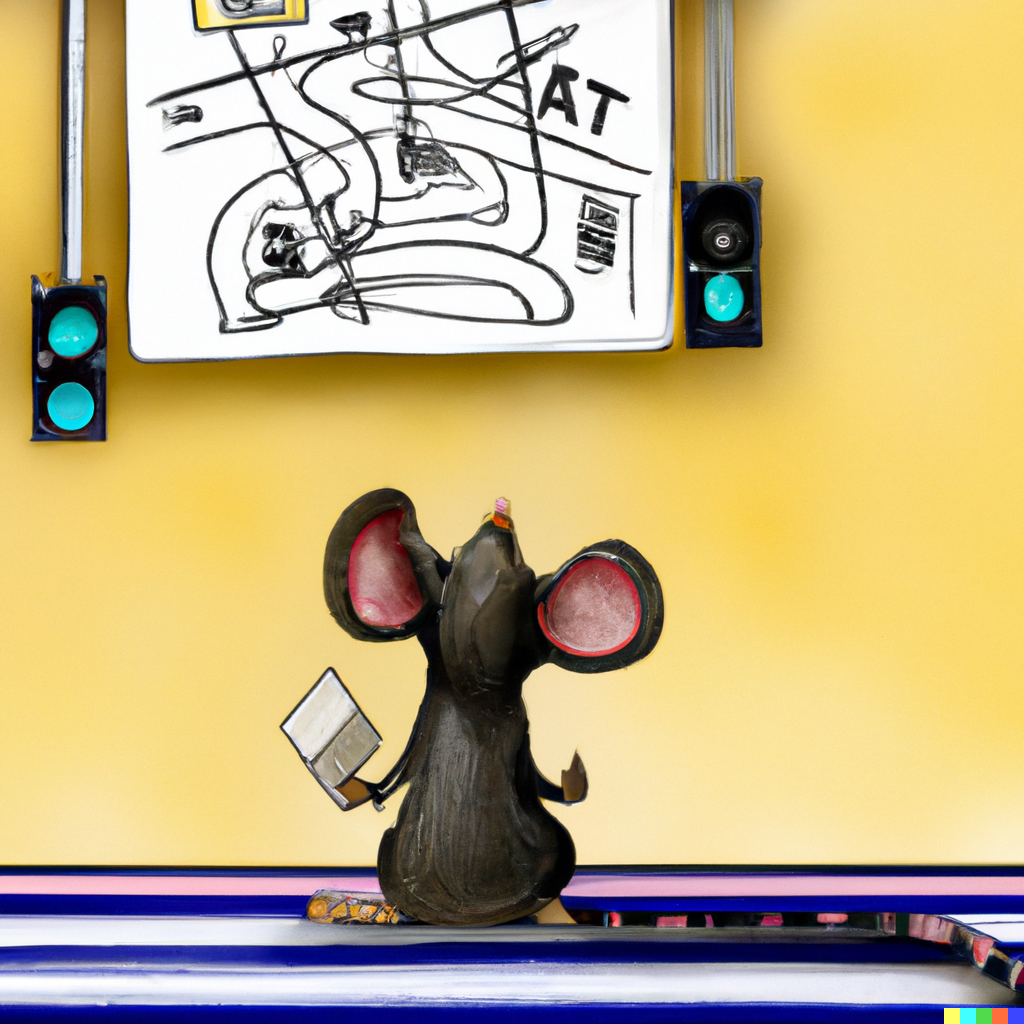

*" digital art a rat thinking about choosing between roads"-Dall-E 2.0, Open-AI*

## **Introduction: How do we keep things in mind**

It is easy to imagine occasions in which we are provided with some information and are required to perform a motor action based on that piece of information. 

take googling on your phone for example: you hear an interesting word or see a perculior notion and reach for your phone to type that word into an online search engine. during execution of this motor behavior (i.e. your hand reaching for the phone in the correct pocket of your jeans), you have that interesting word in your mind.

Here there is an interesting question for a neuroscientist: how does the brain carries the information between the sensory input time (the moment you hear that interesting word) to  the time in which you write those words in your phone keyboard?

Previous studies have implicated specific regions of the cortex called Antero-Lateral Mortor cortex (ALM cortex) in this process. The neurons in rodent ALM have been observed to be active in particular time points between the input of information and execution of the motor action. But how does this stable and persistent neural activity relates to remembering the sensory stimulus?

Here we arrive at the work of Li et al ([doi.org/10.1038/nature17643 [](https://doi.org/10.1038/nature17643)1] 2016, Nature). They chose an intereting approach to answer this question: they asked if disturbing the activity of these stably-active neurons would change the animal's behavious? 

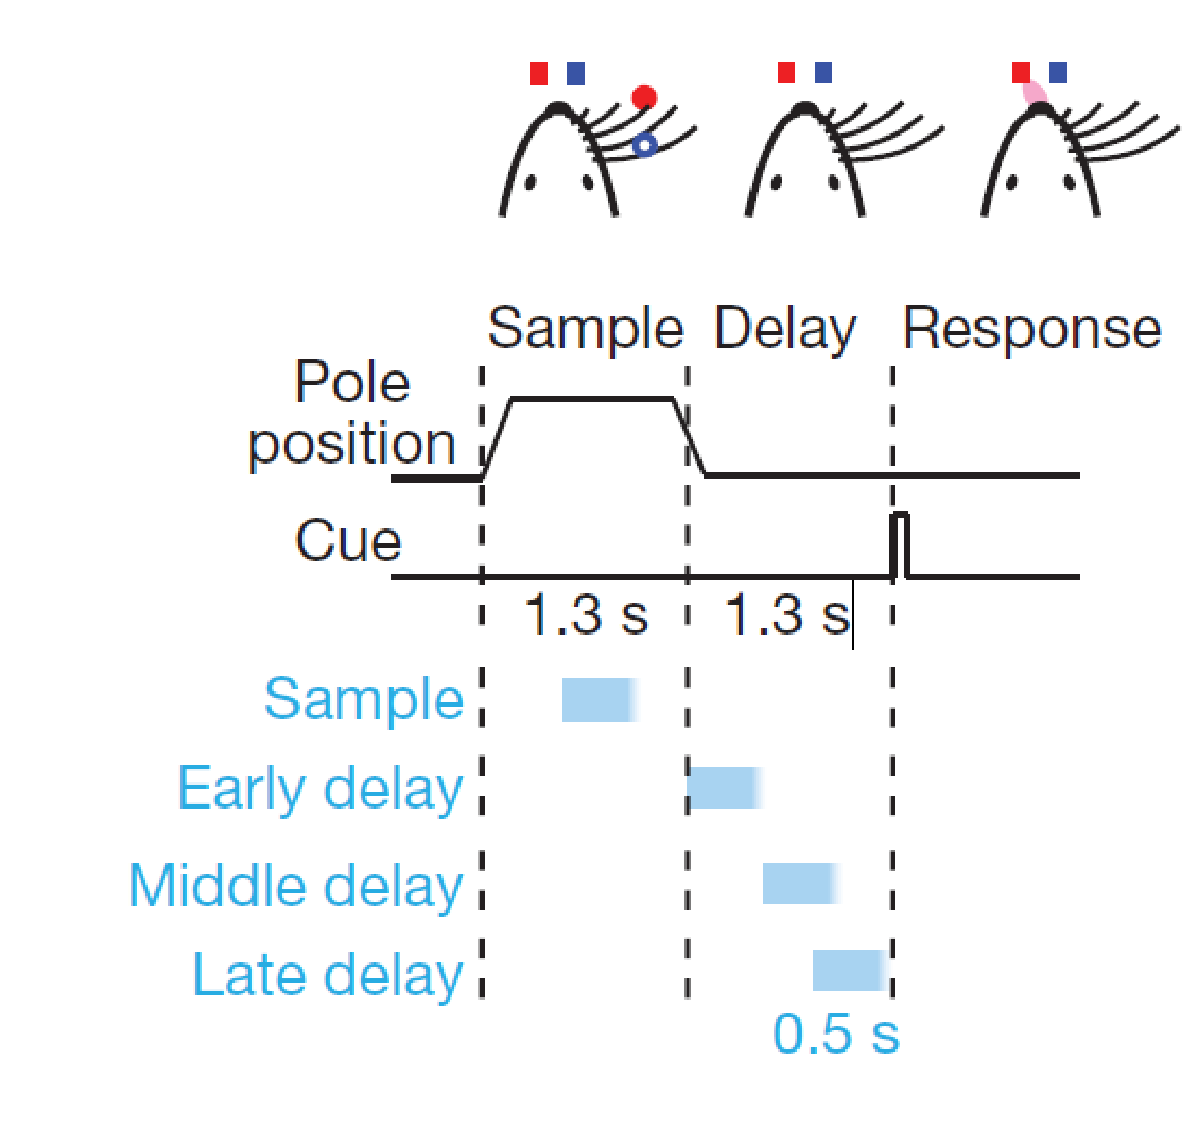

*The experimental paradigm incluring time lines for sampling a sensory stimulus to the whisker, the delay perion, and the go cue to chose the corresponding to the stimuli, *

*blue patches indicate optogenetic [Figure.1 Original Article]*

Li et al, investigated this question using mouse as the model going through a simple behavioral paradigm: the animal would be presented by a pole to its whiskers. then based on the side of the whiskers, after a tone signaling the time to choose, the animal was required to lick a port on either right or left side. Li et all recorded neurons in ALM while briefly silencing the neurons' firing using optogenetic silencing.

would the neurons in ALM stary silencer afte optogenetic stimulation? would the animal forget what it was doing? 

Li et al have published their data on DANDI archive 000011 ([**0.220126.1907**](https://dandiarchive.org/dandiset/000011?search=000011&pos=1)). here we will retrace the main steps taken by Liu et al to see how silencing ALM neurons perturbs memory. 

## **Accessing the experimental data by Li et al**

First lets start by loading the dataset.In this review of the paper i will only use a sub dataset to reduce teh computing time. 

the_file="dataset\sub-255201_ses-20141124_behavior+ecephys+ogen.nwb";
nwbfile = nwbRead(the_file)

nwbfile =   NwbFile with properties:

                                nwb_version: '2.1.0'
                           file_create_date: [1×1 types.untyped.DataStub]
                            general_devices: [2×1 types.untyped.Set]
            general_source_script_file_name: []
                                 identifier: 'ANM255201_2014-11-24_5'
                        session_description: [1×0 char]
                         session_start_time: 2014-11-24T00:00:00.000000-06:00
                  timestamps_reference_time: 2014-11-24T00:00:00.000000-06:00
                                acquisition: [2×1 types.untyped.Set]
                                   analysis: [0×1 types.untyped.Set]
                                    general: [0×1 types.untyped.Set]
                    general_data_collection: []
             general_experiment_description: 'Extracellular electrophysiology recordings with optogenetic perturbatio

as you can see ***.nwb*** files are like a huge pool of  data 'Buckets' with labels such as nwb_version, analysis etc. These data containers may include raw data from the recording setups such as electrophysiological or behavioral time serties, experimental metadata such as experimenter name or experimental sessions' information etc. Furthermore .nwb format provides limited abilities to define  the relationship between the different buckets. For example one can define functions which align different timeseries in different buckets.

The guide to these data containers is usually provided by a `.yml` file but as of this moment there is no quality control process in place to assure all the data have been stored correctly in these containers. As such it is always good practice to validate the data set before committing to analysis. In the current data set for example we find that parts of the recorded data is stored on the behavioural module and other parts are to be found in the units module.

We first need to filter acceptable trials by filtering out the trials in which the animal responded early to the go cue and the trials in which the animal did not hit the intended target:

behavioral_table=nwbfile.intervals_trials.toTable(); % behavioral data for all of the trials

isHit=strcmp('hit',behavioral_table.outcome);        % only select the hit trials
isEarly=strcmp('no early',behavioral_table.early_lick);     % only select the correct hit trials
good_trials=behavioral_table((isHit & isEarly),:);         
good_trials(1:5,:)                                          % the final table for good trials

ans = 5×8 table
    id    start_time    stop_time         task          task_protocol    trial_instruction     early_lick     outcome
    __    __________    _________    _______________    _____________    _________________    ____________    _______

    25      1762.3       1767.8      {'audio delay'}          1              {'right'}        {'no early'}    {'hit'}
    26      1771.2       1776.7      {'audio delay'}          1              {'left' }        {'no early'}    {'hit'}
    27      1779.8       1785.3      {'audio delay'}          1              {'right'}        {'no early'}    {'hit'}
    28      1788.6       1794.1      {'audio delay'}          1              {'left' }        {'no early'}    {'hit'}
   

Further more we see that there is no direct function relating optogenetic stimulations to the actual recording sessions. I wrote an associated live function that describes how can we define a relationship between different data containers directly from the experimental design.

The results are displayed as a table which contains start, stop and the type of optogenetic stimulation.

%get observations
unit_tb=nwbfile.units.toTable();
intervals=unit_tb.obs_intervals{1};  %(start/fin, #trial)

trials_tb = opto_adjust(nwbfile, good_trials)

trials_tb = 226×8 table
    trial_start    trial_finish    id    instruction    go_cue    opto_start    opto_finish       opto_type   
    ___________    ____________    __    ___________    ______    __________    ___________    _______________

      1762.3          1767.8       25     {'right'}     1765.4         NaN           NaN       {'no_stim'    }
      1771.2          1776.7       26     {'left' }     1774.4      1772.3        1772.8       {'sample'     }
      1779.8          1785.3       27     {'right'}       1783         NaN           NaN       {'no_stim'    }
      1788.6          1794.1       28     {'left' }     1791.8         NaN           NaN       {'no_stim'    }
      1797.3          1802.8       29

## **Observing the neural activity**

Now that we have organised our data-set we can start doing some science!

Remember the main goal of the reference paper was to probe how robust the working memory is in ALM cortex. From the anatomical studies it has been suggested that the cortex reponds more strongly to contralateral stimulus. We start by visualising the neural activity in response to ipsilateral (red) and contralateral (blue) stimulus.

First we must set up the experiment variables, it is good coding practice to gather all the relevant constants at one single section :



no_stim_trials=trials_tb(strcmp(trials_tb.opto_type,'no_stim'),:);

%behavioral references
instructions_keys={'left', [1,0,0];                 %here we assign a color code to right and left choices. 
                 'right', [0,0,1]}; 
plot_title_keys={'Left Lick Trials',...
                    'Right Lick Trials'};

%initialize constants
y_offset={'right', 1.1;                         % y axis off-set values for left and right trials visualization 
            'left', 1.2};
y_step=0.005;                                   % off-set steps for the above


unit_ids=unique(unit_tb.id);                      % single cells are referred to as units
units=[unit_ids(1), unit_ids(2), unit_ids(3)];    % an arbitary number of the units to visualize neural response


delay=1.3;                                      % the delay period (from experimental design of the paper)
sample=1.3;                                     % the sampling period (from experimental design of the paper)  
go_time=0;                                      % go time as the reference time


post_trial=1;                                    % time period to be considered after the go cue
pre_trial=3;                                     % time period to be considered before the go cue
trial_duration=pre_trial+post_trial;             



%constants to be used in calculating firing rates 

spiking_bins=100; 
filt_bin=5;                 % moving window size for filtering firing rates

ptsh_time=linspace(-pre_trial,post_trial, spiking_bins-1);
histogram_edges=linspace(-pre_trial,post_trial, spiking_bins);

bin_pertime=spiking_bins/trial_duration;                                % time span of each bin in seconds
go_bn=spiking_bins-post_trial*bin_pertime;                              % the bin number for the go cue
delay_bn=spiking_bins-((post_trial+delay)*bin_pertime);                 % the bin number for the delay period
sample_bn=spiking_bins-((post_trial+sample+delay)*bin_pertime);         % the bin number for the sampling period



bin_times=linspace(-pre_trial, post_trial, floor(trial_duration*bin_pertime)-1);    % the bin number for the sampling period


First we inspect unit selectivity for each individual unit during the different phases of the trials.

Li et all had presented the animals with two types of stimulus: ipsilateral to the site of recording, and contralateral to the site of recordings.

let us see if there is a difference between the patterns of activities in response to ipsilateral and contra lateral 

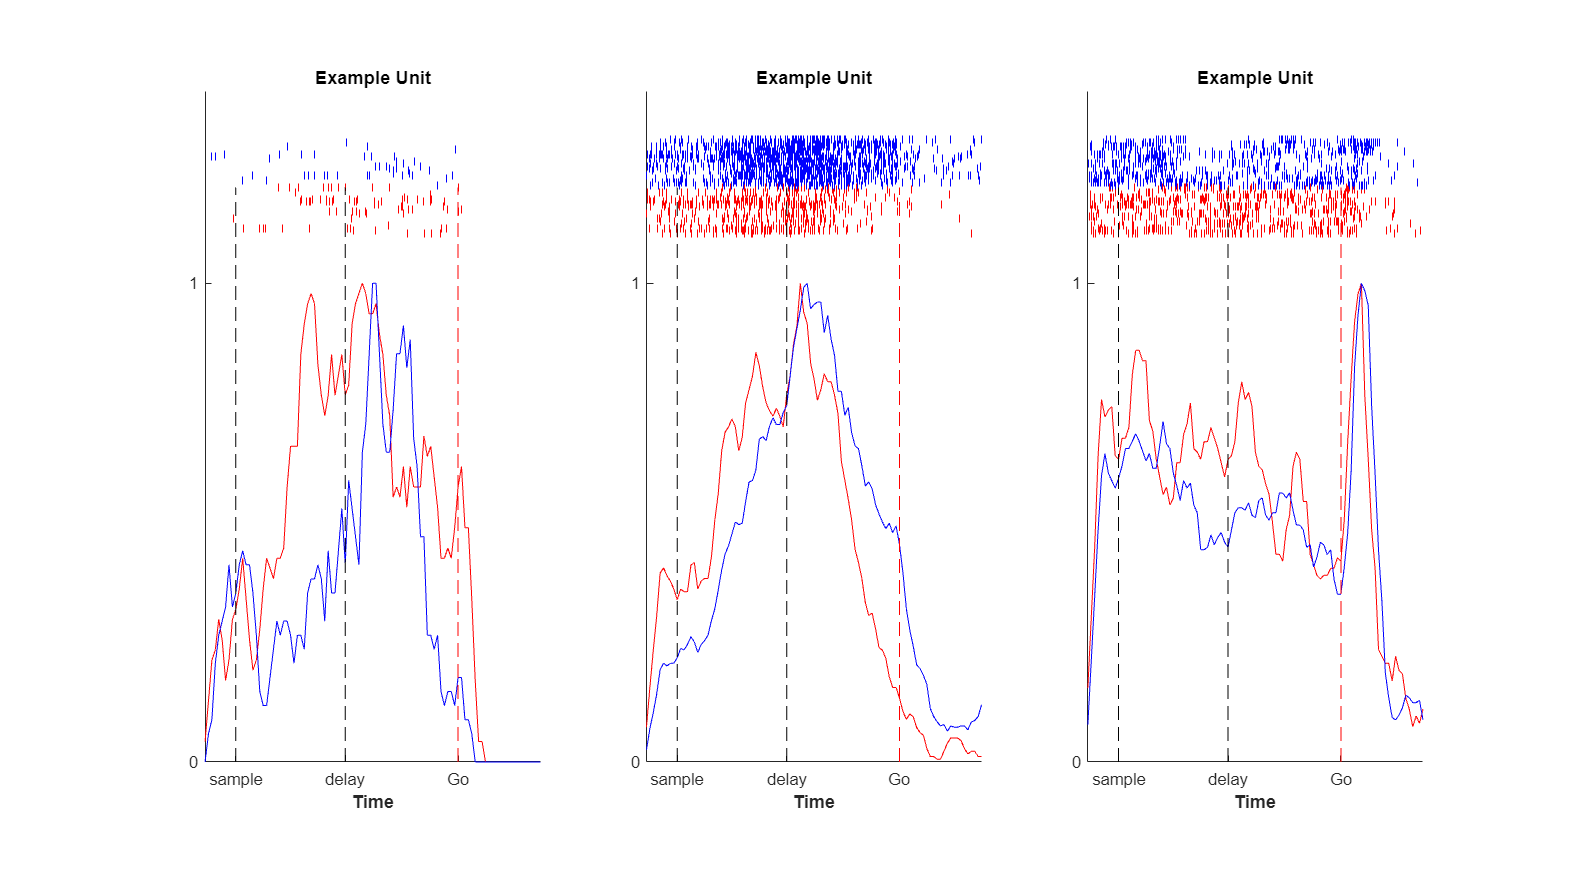

%%
clear figure
 
spikes={};          %initialize cell structure


ptsh_fig = figure('Units','normalized', 'Position', [0.5, 0.5, 0.8, 0.8]);  %Initialize the figure
colormap jet;


for ui=1:numel(units)           % loop over the units
    
    for trial_ky=1:size(instructions_keys, 1)   %loop over left and right stimulus
    
    
        gocues= no_stim_trials(strcmp(no_stim_trials.instruction, instructions_keys{trial_ky,1}),:).go_cue;
        trial_firin=zeros(numel(gocues), numel(histogram_edges)-1);     %thats how you initialize a data strcture. 
    
            for gotime =1:numel(gocues)                                 %loop over trials based on their go times
        
                trial_start=gocues(gotime)-pre_trial; 
                trial_end=gocues(gotime)+post_trial;
                                
                fiers= unit_tb(ui,'spike_times').spike_times{1};            
                spikes{gotime}=fiers(fiers>trial_start & fiers<trial_end)-gocues(gotime);               %get the action potentials in each trial and normalise the time
                trial_firin(gotime, :)=calculate_psth(spikes{gotime}, histogram_edges,  filt_bin);      % store the 
        
            end 
    
        trial_firin(isnan(trial_firin)) = 0;                                                            % filter out good recordings    
        av_reponse=sum(trial_firin, 1)/max(sum(trial_firin, 1));                                        % normalise firing
    
        ax = subplot(1, numel(units), ui , 'Parent', ptsh_fig);                                         % initiate the figure
        hold on;        
        plot(ax, ptsh_time, av_reponse, 'Color', instructions_keys{trial_ky,2})                         % red for ipsi and blue for contra lateral stimulus
    
            for i=1:20
            scatter(ax, spikes{i}, (y_offset{trial_ky,2}+i*y_step), ...                                  % dots for action potentials
                      'Marker', '|', ...
                      'MarkerFaceColor', instructions_keys{trial_ky,2},...
                      'MarkerEdgeColor', instructions_keys{trial_ky,2},...
                       'SizeData', 24)
            end
        
        
        set(ax, 'PlotBoxAspectRatio', [2, 4, 1], 'XTickLabel', [], 'YTickLabel', [])
        title('Example Unit');

        xlabel('Time', 'FontWeight', 'bold');        
        xticks([ptsh_time(floor(sample_bn)) ptsh_time(floor(delay_bn)) ptsh_time(floor(go_bn))])
        xticklabels(ax, {'sample','delay','Go'})
        
        yticks(ax, [0 1])
        yticklabels(ax,['0'; '1'])
        
       

        line([ptsh_time(floor(sample_bn)), ptsh_time(floor(sample_bn))], [0, y_offset{trial_ky,2}], 'LineWidth', 0.6, 'Color','k','LineStyle','--') %sample line
        line([ptsh_time(floor(delay_bn)), ptsh_time(floor(delay_bn))], [0, y_offset{trial_ky,2}], 'LineWidth', 0.6, 'Color','k','LineStyle','--')   %delay line
        line([ptsh_time(floor(go_bn)), ptsh_time(floor(go_bn))], [0, y_offset{trial_ky,2}], 'LineWidth', 0.6, 'Color','r','LineStyle','--')         %go line
        
       
    end

end 

There is a lot going on in these firing patterns. differences betwrrn firing rates of each unit at different stages of the experiment are As we can see, there are clear differences in the ipsilateral and contralateral response of the individual cells, but these differences are not immediately apparent by just visualy inspecting the histograms.

## **Selectivity: Probing the functionality of neurons**

 We need a more regorous measure to be able to distinguish the preference of ALM neurons. The authors developed a measure to assess this difference in lateral response more rigorously. They defined unit selectivity as the difference of between unit response to contralateral and ipsilateral stimulus:

## 
$$\textrm{Selectivity}=F_{\textrm{contralateral}} -F_{\textrm{ipsilateral}}$$


in which ***F ***indicates firing rate To drive this measure we first need to segregate each response to ipsilateral and contralateral responses. 

to consider repeated trials I implemented this definition as such:


$$\textrm{UnitSelectivity}=\sum_{\textrm{trial}} F_{\textrm{unit}\to \textrm{left}} \left\lbrack t_i \right\rbrack -\sum_{\textrm{trial}} F_{\textrm{unit}\to \textrm{right}} \left\lbrack t_i \right\rbrack \;$$


in which $t_i$ is the sampling time point and $F_{\textrm{unit}\to \textrm{left}}$ inidicates firing rate of the specific unit in response to the distinct the function to extract lateral responses and calculate the unit selectivity toward the contralateral stimulus. 


spiking_threshold=2;
unit_selectivity=[];            %it is good coding practice to allocate a precise amount of memory to be used by the 


left_t=no_stim_trials(strcmp(no_stim_trials.instruction, instructions_keys{1}),:).go_cue;       %go cue times for trials with left (contra-lateral) instruction
right_t=no_stim_trials(strcmp(no_stim_trials.instruction, instructions_keys{2}),:).go_cue;      %go cue times for trials with right (ipsi-lateral) instruction


unit_selectivity = unt_selectivity(left_t, right_t, pre_trial, post_trial, unit_ids, unit_tb, histogram_edges,  filt_bin); %runing the function for calculating selectivity in each trial 

unit_selectivity is a matrix,  each row of which is the selectivity of a unit during the trials. First we need to inspect each individual unit's selectivity for each individual unit during the different phases of the trials:

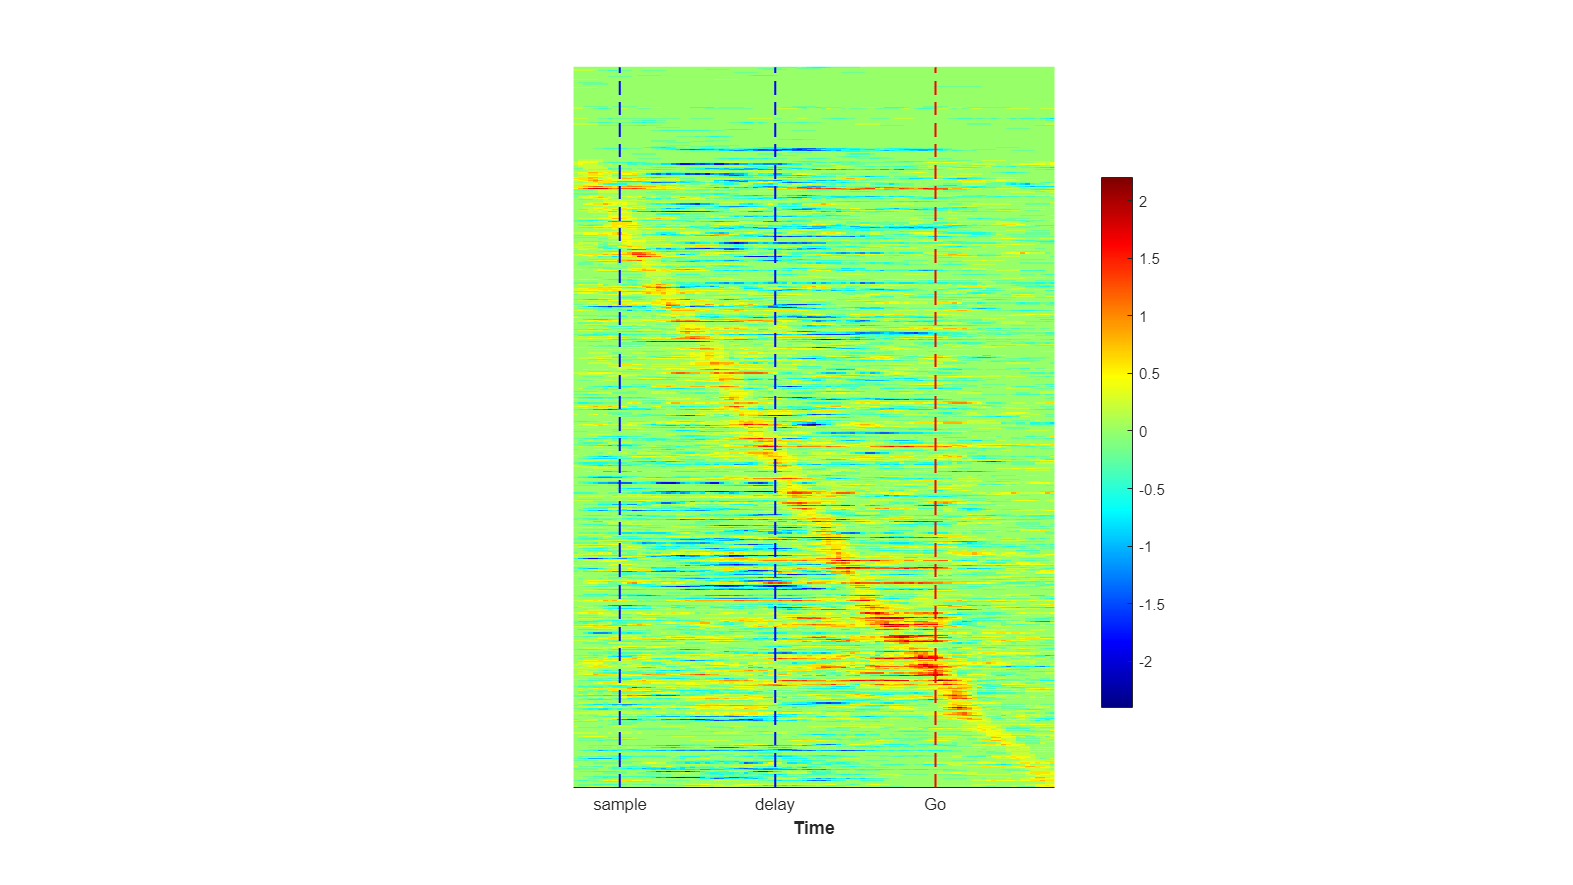


clear figure
fig = figure('Units','normalized','Position',[0 0 1 1]);

colormap jet


ax = subplot(1, 1, 1, 'Parent', fig);
hold on;

[~, tmp] = max(unit_selectivity, [], 2);        % get the peak selectivity
[~, sorted_idx] = sort(tmp,'descend');          % sort the the trials based on the peak selectivity 

selectivity_pic = unit_selectivity(sorted_idx, :); % apply the sorting on the  
imagesc(ax, selectivity_pic );              %  draw the image


set(ax,'PlotBoxAspectRatio', [2, 3, 1], 'XTickLabel', [], 'YTickLabel', [])
ylabel('Trials');
ax.YAxis.Visible='off';
colorbar(ax,'eastoutside', 'position',[.7 .2 .02 .6]);

xlabel('Time', 'FontWeight', 'bold');
xticks([floor(sample_bn) floor(delay_bn) floor(go_bn)])
xticklabels(ax, {'sample','delay','Go'})


% The lines as before
line(ax,[floor(sample_bn), floor(sample_bn)], [0, size(selectivity_pic,1)], 'LineWidth', 1.2, 'Color','b','LineStyle','--')
line([floor(delay_bn), floor(delay_bn)], [0, size(selectivity_pic,1)], 'LineWidth', 1.2, 'Color','b','LineStyle','--')
line([floor(go_bn), floor(go_bn)], [0, size(selectivity_pic,1)], 'LineWidth', 1.2, 'Color','r','LineStyle','--')

xlim([0.5 99.5])
ylim([0 649])

In the figure above the warm colours On the right bottom corner of the heat map indicate strong selectivity of a subpopulation of the neurons toward contralateral stimulus, while the animal is preparing to perform the motor action. This is were we can see the thoughts going on in the animal’s head: ”I need to lick the contralateral port and there will be a yummy reward!”. we need to make sure this is representitive of the population's activity. 

let us see how are mean and statistical for the statisticak distributiob of  momen-to moment selectivity gave been look like. 

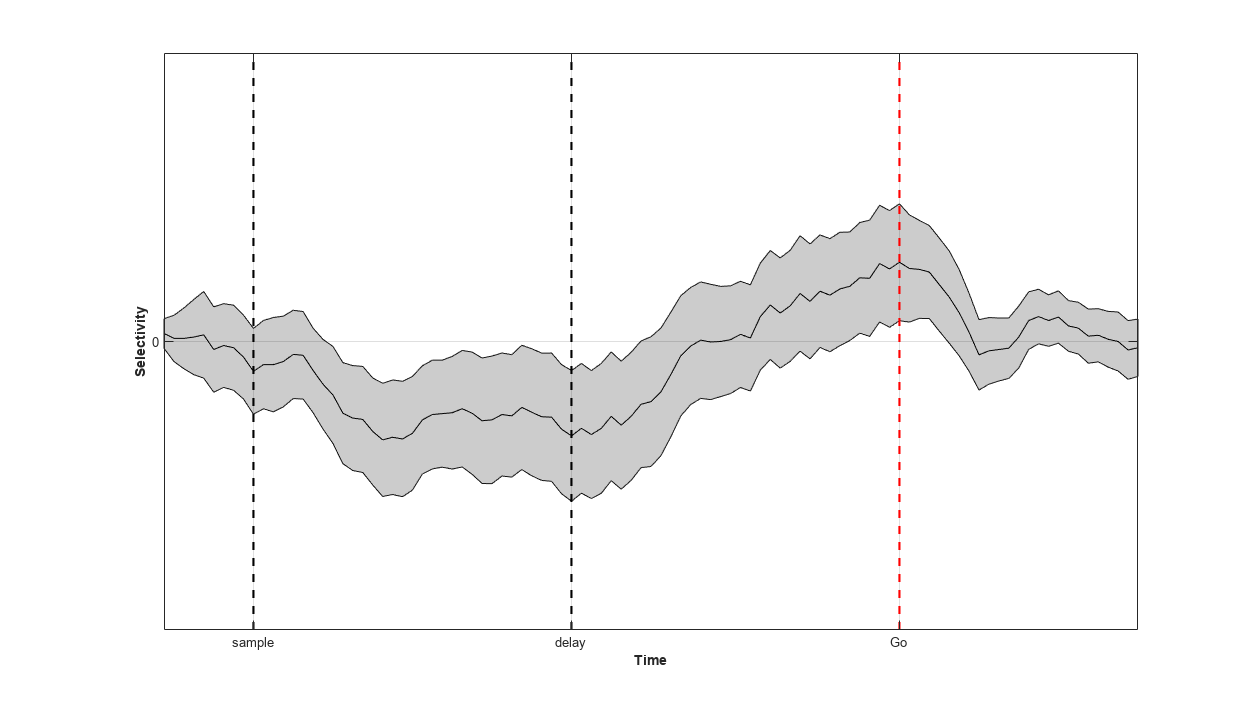


% Initialize the plotting values




n=size(unit_selectivity, 2);
sqrn_n=sqrt(n); %square root of n to calculate standard error of the means.

sd=std(unit_selectivity,0,1);
mean_selectivity=mean(unit_selectivity,1);

% shaded areas
inBetweenRegionX =[];
inBetweenRegiony =[];

inBetweenRegionX =[bin_times, fliplr(bin_times)];                                           % x-coordinates of the shaded region
inBetweenRegionY = [mean_selectivity+(sd/sqrn_n), fliplr(mean_selectivity-(sd/sqrn_n))];    % y-coordinates of the shaded region based on standard error of the means


clear figure
figure = figure('Units','normalized','Position',[0 0 1 1]);
ax=gca;

fill( inBetweenRegionX, inBetweenRegionY,'k', 'FaceAlpha',0.2, 'EdgeAlpha',0.9); % Display the area first so it will be in the background.
hold on;

plot(bin_times, mean_selectivity, 'Color','k')  % Now plot the curves and markers on top of the area.

xlabel('Time', 'FontWeight', 'bold');
xticks([ptsh_time(floor(sample_bn)) ptsh_time(floor(delay_bn)) ptsh_time(floor(go_bn))])
xticklabels(ax, {'sample','delay','Go'})

ylabel('Selectivity', 'FontWeight', 'bold');
yticks([ptsh_time(floor(sample_bn)) ptsh_time(floor(delay_bn)) ptsh_time(floor(go_bn))])
yticklabels(ax, {'sample','delay','Go'})
yticks(ax, [0 1])
yticklabels(ax,['0'; '1'])
ax.YLim=[-0.2,0.2];



line([ptsh_time(floor(sample_bn)), ptsh_time(floor(sample_bn))], ax.YLim, 'LineWidth', 1.6, 'Color','k','LineStyle','--')
line([ptsh_time(floor(delay_bn)), ptsh_time(floor(delay_bn))], ax.YLim, 'LineWidth', 1.6, 'Color','k','LineStyle','--')
line([ptsh_time(floor(go_bn)), ptsh_time(floor(go_bn))], ax.YLim, 'LineWidth', 1.6, 'Color','r','LineStyle','--')


grid on;
hold off;

## Using optogenetics to manipulate selectivity 

We see that there is a positive selectivity toward the end of the delay period just before the animal performs motor movement.

Now we have an empirical measure of neural activity that clearly illustrates how ALM cortex stores information prior to execting action based on those information. This measure enables us to probe how perturbation of ALM activity  effects storage and retrieval of information.

To pertube ALM activity the authors used optogenetic silencing of neural activity. In this technique first specific light receptors are delivered to cortical cells using viral injections. These artificial receptors could be activated by delivering light pulses into the brain. 

Let us select the experiments in which the optogenetic stimulus was delivered in the middle of the delay period and see how selectivity of neural activity changes after this perturbation.



delay_trials=trials_tb(strcmp(trials_tb.opto_type,'mid_delay'),:);                      % select the trials in which the optoenetic stimulus happened at mid-delay phase, according to figure.1

left_t=delay_trials(strcmp(delay_trials.instruction, instructions_keys{1}),:).go_cue;       %left-cue trials' go time
right_t=delay_trials(strcmp(delay_trials.instruction, instructions_keys{2}),:).go_cue;      

unit_selectivity = lateral_firings(left_t, right_t, pre_trial, post_trial, unit_ids, unit_tb, histogram_edges,  filt_bin);

Unrecognized function or variable 'lateral_firings'.


n=size(unit_selectivity, 1);
clear figure
figure = figure('Units','normalized','Position',[0 0 1 1]);
ax=gca;

%function seectivity_fig is a short hand for all the codes for the previous
%                                   figure which showed average selectivity of the trials.

ax=selcctivity_fig(unit_selectivity, n, bin_times,sample_bn,ptsh_time,delay_bn, go_bn,  ax);



patch_vertices=[-0.3 0.15; -0.8 0.15; -0.8 0.18; -0.3 0.18]; % to demonstrate the optogenetic stimulus with a ble patch

patch(ax,...   
        'Faces', 1:4,...
        'Vertices', patch_vertices,...
        'FaceColor', '#B3D3EC',...  % light blue shading
        'EdgeColor', 'none',...
        'FaceAlpha', 0.8);

As we can see during the delivery of the light there is a visible change in the selectivity of neural activity at ALM, but immediately after end of light stiulation the selectivity is recovered toward the positive values.

The authors follow up this observation with decativating ALM activity in multiple time windows, ipsilateral or contralateral deactivation of ALM activity using optogenetics and lesions to confirm that such persistent activity arises from arobust dynamic system which could be abolished by deactivation of ALM activity bilaterally.

This is indeed what the authors report  in the initial parts of the paper. with much greater details and analysis which included dimensionality reduction techniques, deactivation of multiple other brain regions and different temporal manipulations. It is remarkable that we can trace the footsteps of other scientists using their deposited data and quite possibly gain new insights into their research. 

## Refrences:

    1.    

    2.    Li N, Daie K, Svoboda K, Druckmann S. Robust neuronal dynamics in premotor cortex during motor planning. Nature. 2016 Apr 28;532(7600):459-64. [doi: 10.1038/nature17643](doi: 10.1038/nature17643). Epub 2016 Apr 13.             Erratum in: Nature. 2016 Sep 1;537(7618):122. PMID: 27074502; PMCID: PMC5081260